# Analysis pH dependence

%This script was used to see pH dependence and to extract BT
% 37° C
 t=readtable("\\146.48.73.104\Data\Data_QNAP\Calibration Chloride Sensors\iClima 1P\Stellaris\Stellaris\analisi\filesource_pH_37C.txt","Delimiter",'tab',...
     'FileType','text','NumHeaderLines',0);

% 32° C
%t=readtable("\\146.48.73.104\Data\Data_QNAP\Calibration Chloride Sensors\iClima 1P\Stellaris\Stellaris\analisi\filesource_pH_32C.txt","Delimiter",'tab',...
%    'FileType','text','NumHeaderLines',0);

disp(t)

     pH     Cl    T                                                                                    Filename                                                                               
    ____    __    __    ______________________________________________________________________________________________________________________________________________________________________

       6    0     37    {'\\146.48.73.104\Data\Data_QNAP\Calibration Chloride Sensors\iClima 1P\Stellaris\Stellaris\20240229 MEF\pH 6\Emission  6  piastra 5_spectra.mat'                    }
       6    0     37    {'\\146.48.73.104\Data\Data_QNAP\Calibration Chloride Sensors\iClima 1P\Stellaris\Stellaris\20240229 MEF\pH 6\Emission  6   piastra 11_spectra.mat'                  }
       6    0     37    {'\\146.48.73.104\Data\Data_QNAP\Calibration Chloride Sensors\iClima 1P\Ste

n_el = size(t,1);
s = struct( 'ph',cell(n_el,1), 'wl_em',cell(n_el,1),...
    'wl_ex',cell(n_el,1), 'data',cell(n_el,1));

for i=1:n_el
    fn = t{i,"Filename"};
    tmp_ratio = load(fn{1});
    s(i).ph = t{i,'pH'};
    s(i).wl_ex = tmp_ratio.wl_ex;
    s(i).wl_em = tmp_ratio.wl_em;
    s(i).data  = tmp_ratio.vals_noBkg;
end

Error using load
Unable to find file or directory '\\146.48.73.104\Data\Data_QNAP\Calibration Chloride Sensors\iClima 1P\Stellaris\Stellaris\20240229 MEF\pH 6.84\Emission   piastra 1_spectra.mat'.


% per ora tutte le wavelength sono uguali
wl_ex = s(1).wl_ex;
wl_em = s(1).wl_em;
n_ex = numel(wl_ex);
n_em = numel(wl_em);

## Set emission filters

bp_green = [520 555]; % 2P 527/70
bp_red   = [590 625]; % 2P 607/70


## Measure bleedthrough

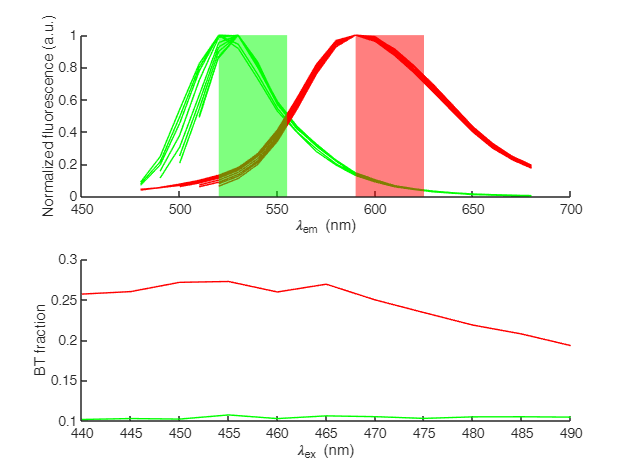

spectra_gr = load('\\146.48.73.104\Data\Data_QNAP\Calibration Chloride Sensors\iClima 1P\Stellaris\Stellaris\analisi\average_spectra_pH7.2_20240524.mat');
% emission wavelengths are always the same
% also excitation wavelengths are the same here

alpha = zeros(numel(spectra_gr.wl_ex),1);
beta = alpha;

bp_green_logi = spectra_gr.wl_em >= bp_green(1) & spectra_gr.wl_em <= bp_green(2);
bp_red_logi   = spectra_gr.wl_em >= bp_red(1)   & spectra_gr.wl_em <= bp_red(2);
for iex=1:numel(alpha)
    alpha(iex) = sum( spectra_gr.Rem(iex,bp_green_logi) ) ./ sum( spectra_gr.Rem(iex,bp_red_logi) );
    beta(iex)  = sum( spectra_gr.Gem(iex,bp_red_logi  ) ) ./ sum( spectra_gr.Gem(iex,bp_green_logi) );
end
alpha_ex = alpha(ismember(spectra_gr.wl_ex,wl_ex));
beta_ex  = beta (ismember(spectra_gr.wl_ex,wl_ex));

figure
subplot(2,1,1)
hold on
plot(wl_em,(spectra_gr.Gem./max(spectra_gr.Gem,[],2))','g')
plot(wl_em,(spectra_gr.Rem./max(spectra_gr.Rem,[],2))','r')
xlabel('\lambda_e_m (nm)')
ylabel('Normalized fluorescence (a.u.)')
p=patch('Faces',[1 2 3 4 1],'Vertices', [bp_green(1),0; bp_green(2),0; bp_green(2),1; bp_green(1),1],...
    'edgecolor','none','facecolor','g','facealpha',0.5);
patch('Faces',[1 2 3 4 1],'Vertices', [bp_red(1),0; bp_red(2),0; bp_red(2),1; bp_red(1),1],...
    'edgecolor','none','facecolor','r','facealpha',0.5)
xlim([450 700])
subplot(2,1,2)
hold on
plot(wl_ex,alpha_ex,'r')
plot(wl_ex,beta_ex, 'g')
xlabel('\lambda_e_x (nm)')
ylabel('BT fraction')

## Integrate G and R

for i=1:n_el
    % correct excitation normalizing for the tail of the red emission
    tmp_ratio = s(i).data;
    % tmp_ratio = tmp_ratio ./mean( tmp_ratio(:,wl_em>=650,:,:) , 2, 'omitnan');
    % collect emission
    ch1 = squeeze(sum( tmp_ratio(:,bp_green_logi,:,:), 2));
    ch2 = squeeze(sum( tmp_ratio(:,bp_red_logi  ,:,:), 2));
    % remove BT
    s(i).green = ch1 - ch2.*alpha_ex;
    s(i).red   = ch2 - ch1.*beta_ex;
    s(i).ratio = s(i).green ./ s(i).red;
end


## pH and exc spectra

phs = unique(t.pH);
n_ph = numel(phs);
remove_outliers = true;
% thr_red = 1; % remove rois with red values lower than this
for i=1:numel(s)
    % s(i).bad = any(s(i).red<thr_red,1);
    if remove_outliers
        [goodrois,x] = removeoutliers_rms(s(i).ratio,5,5,false);
        s(i).bad = ~ismember(1:size(s(i).ratio,2),goodrois);
    else
        s(i).bad = false(1,size(s(i).ratio,2));
    end

    % s(i).bad = false(); 

    fprintf("file %i removed %i rois\n", i, sum(s(i).bad) )

end

file 1 removed 36 rois
file 2 removed 38 rois
file 3 removed 32 rois
file 4 removed 34 rois


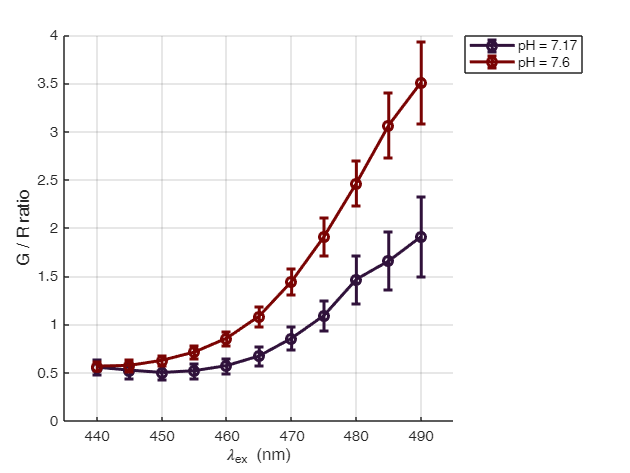



spectra_ph = nan(n_ex,n_ph);
cols = turbo(n_ph);
figure
axes
hold on
for i=1:n_ph
    tmp_ratio = cat(2, s( phs(i)==[s.ph]).ratio );
    tmp_bad   = cat(2, s( phs(i)==[s.ph]).bad );
    

    med = median(tmp_ratio (:,~tmp_bad),2);
    err = mad   (tmp_ratio (:,~tmp_bad),1,2);
    erp = errorbar(wl_ex,med,err,'o-','color',cols(i,:),'linewidth',2,...
        'DisplayName',sprintf("pH = %3g",phs(i)));
    spectra_ph(:,i) = med;
end
xlabel('\lambda_e_x (nm)')
ylabel('G / R ratio')
set(gca,'yscale','linear')
xlim([435 495])
grid on
legend('location','northeastoutside')

## plot individual ph

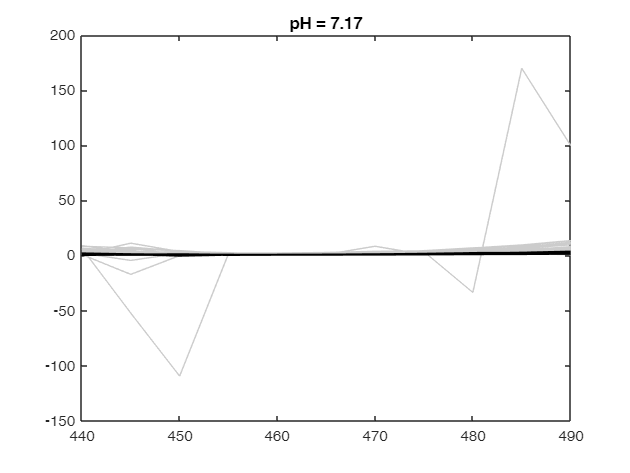

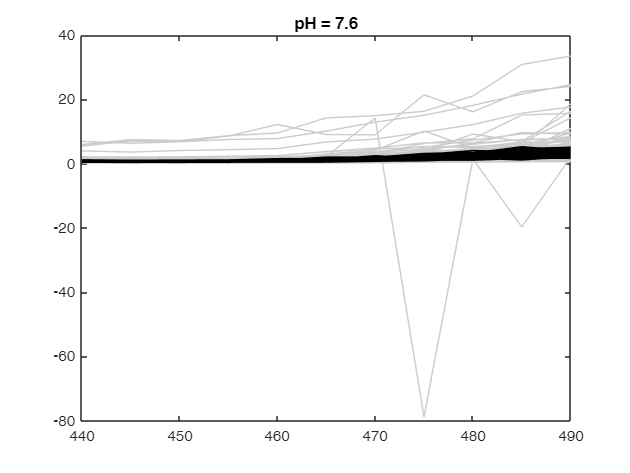

for i=1:n_ph
    % tmp_ratio = cat(2, s( phs(i)==[s.ph]).red );
    tmp_ratio = cat(2, s( phs(i)==[s.ph]).ratio );
    tmp_bad   = cat(2, s( phs(i)==[s.ph]).bad );
    figure
    if remove_outliers
        plot(wl_ex,tmp_ratio(:,tmp_bad),'-','color',[0.8 0.8 0.8])
        hold on
    end
    plot(wl_ex,tmp_ratio(:,~tmp_bad),'-k')
    % plot(wl_ex,spectra_ph(:,i),'o-k','linewidth',2)
    title(sprintf('pH = %3g',phs(i)))
end

## fitta

% decidi basi

range_wl_fit = 1:7;

ph1=6;
ph2=8;
base1 = spectra_ph(:,phs==ph1)';
base2 = spectra_ph(:,phs==ph2)';
results = struct('ph',[],'delta',[],'epsilon',[],'theta',[]);
for i=1:n_ph
    tmp_ratio = cat(2, s( phs(i)==[s.ph]).ratio );
    tmp_bad   = cat(2, s( phs(i)==[s.ph]).bad );
    good_ratio = tmp_ratio (range_wl_fit,~tmp_bad);
    results(i).ph = phs(i);
    [~, results(i).delta, results(i).epsilon, results(i).theta] = compute_pH(good_ratio',base1(range_wl_fit),base2(range_wl_fit),[],[]);
end

Index exceeds array bounds.

save_dir = "D:\LabData\Chloride_Imaging\calibraz\analisi";
timenow=string(datetime);
save(save_dir+filesep+"calibraz_pH_"+strrep( strrep(timenow,':','_'), ' ', '_')+".mat",'results','ph1','ph2','base1','base2','phs','wl_ex')

% esporta
nums = arrayfun(@(x)numel(x.delta),results);
n_max = max(nums);
out = nan(n_max,3*n_ph);
for i=1:n_ph
    out( 1:nums(i), 3*(i-1)+1) = results(i).delta;
    out( 1:nums(i), 3*(i-1)+2) = results(i).epsilon;
    out( 1:nums(i), 3*(i-1)+3) = results(i).theta;
end

out2 = sprintf( [repmat('%.6f\t',1,n_ph*3) '\n'], out' );
out2 = strrep(out2,'NaN','');
clipboard('copy',out2)


